# A Estimation curve VS different S_EI

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

历时 25.923609 秒。



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

历时 8.799946 秒。



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

历时 7.623092 秒。



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

历时 2.868652 秒。


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.024; S_EI = 0.055*0.024/0.029;  
% check S_II: subplot ind
% S_II = 0.062; 
% S_II = 0.120; 
S_II = 0.159; 
% check S_IE: x-position of the interval
% S_IE = 0.32*S_II;
% S_IE = 0.2*S_II;
 S_IE = 0.10*S_II;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

% Check amb. That's for differnet figures
% rE_amb = 0.54; rI_amb = 0.54;
rE_amb = 0.54; rI_amb = 0.54;
% Length of the interval %% Replace S_EI by testing values
S_EItest = linspace(2,2.7,10)*S_EE;

## Test smaller stepsize

cluster = gcp('nocreate');
if isempty(cluster)
    cluster = parpool([4 64]);
    cluster.IdleTimeout = 1200;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).



Fr_NoFix_ref = zeros(2,length(S_EItest));
mV_NoFix_ref = zeros(2,length(S_EItest));
Fr_NoFixVar_ref = zeros(2,length(S_EItest));
mV_NoFixVar_ref = zeros(2,length(S_EItest));
Fr_NoFixTraj_ref = cell(length(S_EItest),1);
mV_NoFixTraj_ref = cell(length(S_EItest),1);

loopCount_ref = zeros(1,length(S_EItest)); % count the number of loops
ConvIndi_ref = logical(loopCount_ref);

SampleNum = 100;
MaxNum = 500;
h = 1;
SimuT = 20*1e3;
tic
parfor S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    tic
    [Fr_NoFixTraj_ref{S_EIInd},mV_NoFixTraj_ref{S_EIInd},loopCount_ref(S_EIInd),ConvIndi_ref(S_EIInd)]...
                  = MeanFieldEst_BkGd_Indep_StepSize_Testref(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum,h,SimuT);
                                        
    toc
end

历时 15.494256 秒。
历时 15.522451 秒。
历时 14.793372 秒。
历时 11.165048 秒。
历时 11.760129 秒。
历时 11.369794 秒。
历时 10.741040 秒。
Firing rates unconverged
历时 37.756047 秒。
历时 10.589539 秒。
历时 8.505836 秒。


toc

历时 49.934341 秒。



for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_ref(:,S_EIInd) = mean(Fr_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),2);
    mV_NoFix_ref(:,S_EIInd) = mean(mV_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar_ref(:,S_EIInd) = var(Fr_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar_ref(:,S_EIInd) = var(mV_NoFixTraj_ref{S_EIInd}(:,end-SampleNum:end),0,2);
end


## Network Simulation

S_EE = 0.024, S_EI = 0.0648, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

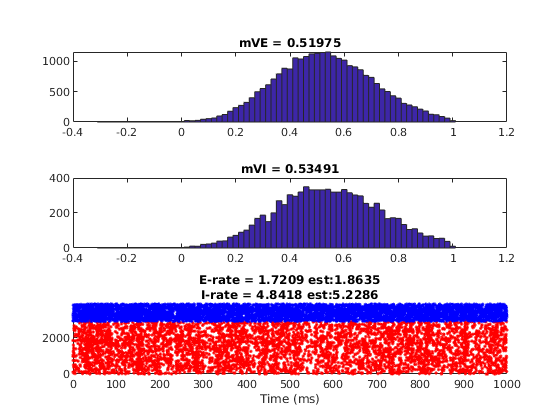

S_EE = 0.024, S_EI = 0.0648, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

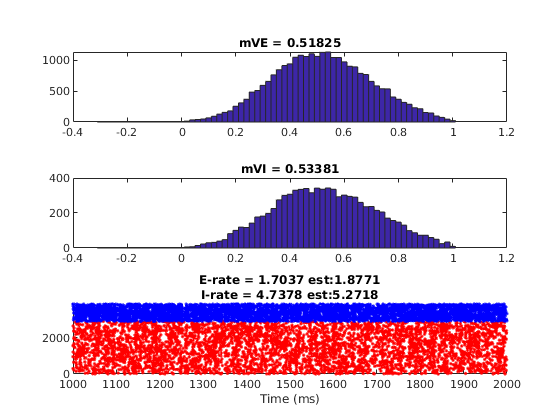

S_EE = 0.024, S_EI = 0.0648, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.062933, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.062933, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.062933, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.061067, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.061067, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.061067, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

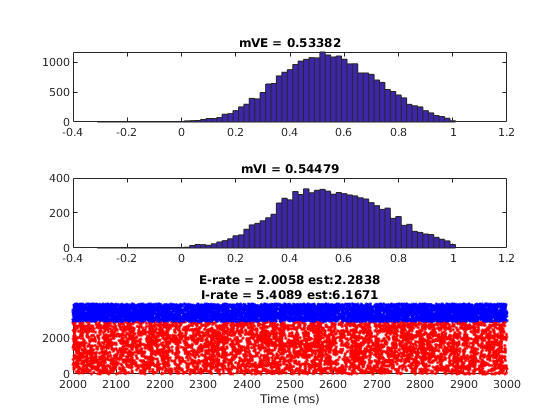

S_EE = 0.024, S_EI = 0.0592, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

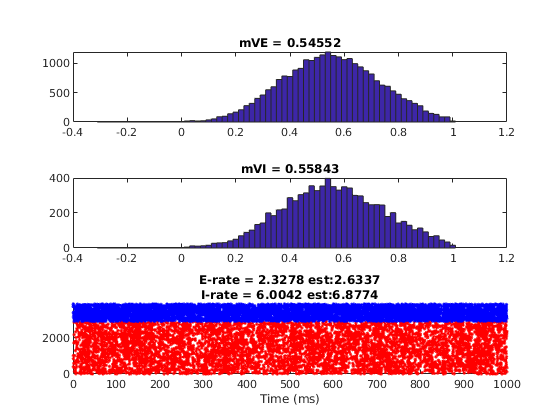

S_EE = 0.024, S_EI = 0.0592, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.0592, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.057333, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.057333, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.057333, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.055467, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.055467, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

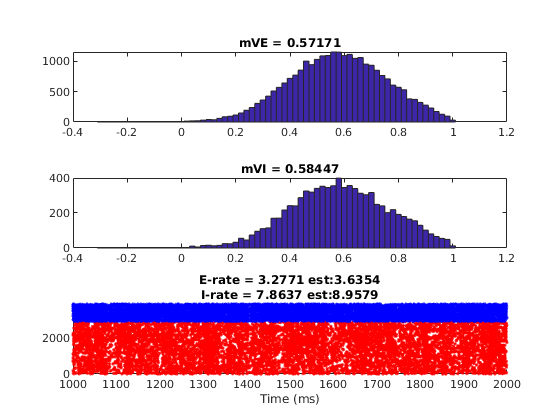

S_EE = 0.024, S_EI = 0.055467, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

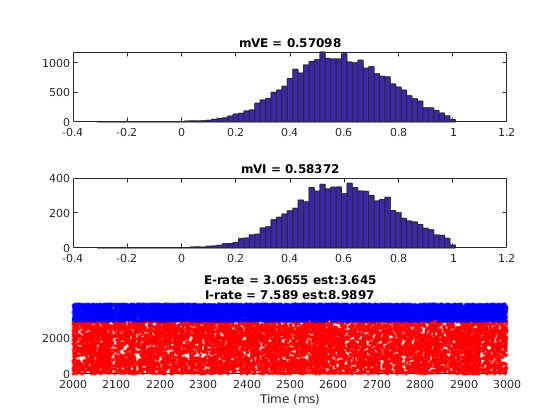

S_EE = 0.024, S_EI = 0.0536, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.0536, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.0536, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

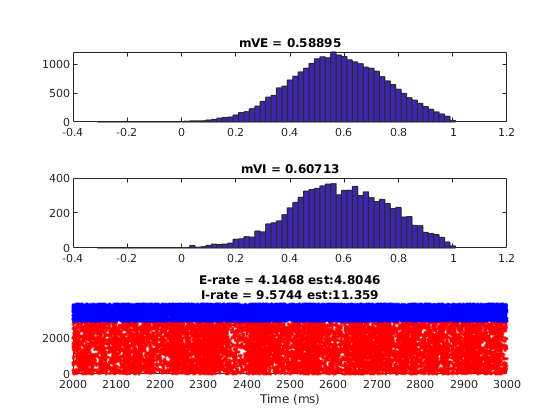

S_EE = 0.024, S_EI = 0.051733, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.051733, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

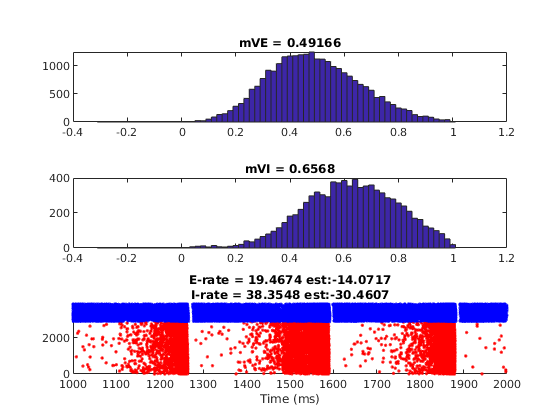

S_EE = 0.024, S_EI = 0.051733, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

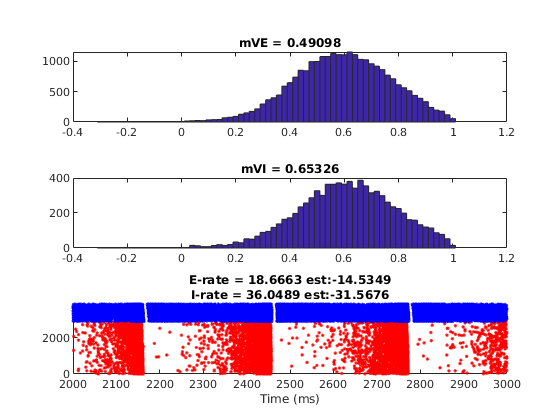

S_EE = 0.024, S_EI = 0.049867, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.049867, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

S_EE = 0.024, S_EI = 0.049867, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

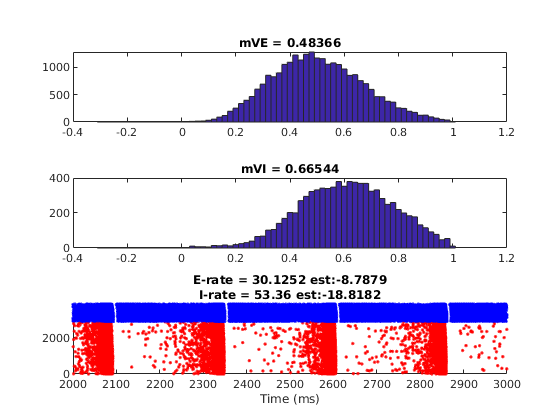

S_EE = 0.024, S_EI = 0.048, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

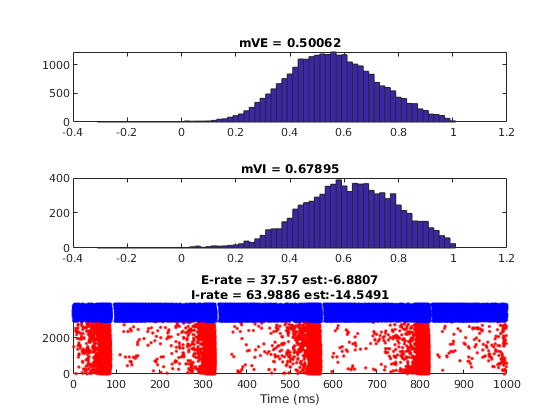

S_EE = 0.024, S_EI = 0.048, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

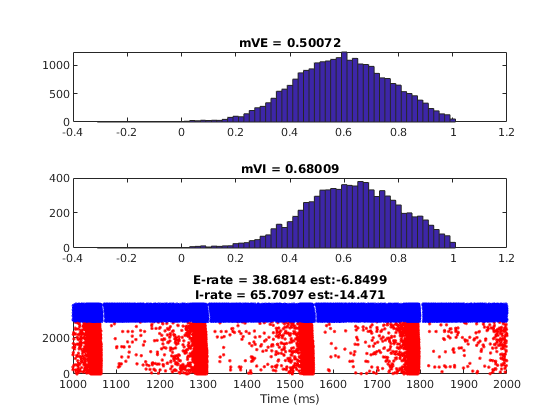

S_EE = 0.024, S_EI = 0.048, S_IE = 0.0159, S_II = 0.159
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.54, rI_amb = 0.54

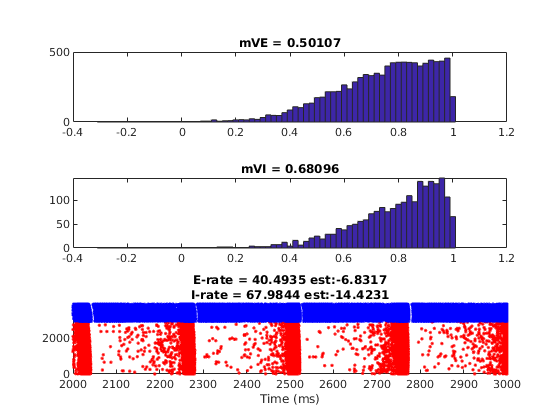

T = 3000; sampleT = 2; SimulationT = 1000;

Fr_NW = zeros(2,length(S_EItest));
mV_NW = zeros(2,length(S_EItest));
Fr_OneStep = zeros(2,length(S_EItest)); % one step MF estimation using network mV

Fr_NWTraj = cell(1,length(S_EItest)); % tracing network firing rate 
FrWinSize = 200; FrWinStep = 50;
FrWinNum = floor((T-FrWinSize)/FrWinStep) + 1;

E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
    
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

for S_EIInd = length(S_EItest):-1:1
    S_EI = S_EItest(S_EIInd);
    %E_SpHis= []; I_SpHis=[];
    E_Sp = []; I_Sp = [];
    VE_T = []; VI_T = [];
    sampleN = floor(sampleT/dt); % sample each 2 ms
    SimulationN = floor(SimulationT/dt); % show and check every 200ms
    for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,...
          oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
     oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
          oGI_ampa_D,oGI_nmda_D,oGI_gaba_D] = ...
          V1NetworkUpdate(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,...
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                          S_amb,lambda_E,lambda_I,rE_amb,rI_amb);
                      
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                              GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                              GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;

% When reaching every 200ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>500
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
                         ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
                         'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
                         ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
    
    fprintf(ParameterDisp)
    h = figure('Name','TestRaster');
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    

    %E_Ind = 10000:13000; I_Ind = 3300:4300;
    scatterE = find(ismember(E_Sp(:,1),E_Ind));
    scatterI = find(ismember(I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

    WinSize = SimulationT;
    T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
    E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
    I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
    E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
    I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

    f_EnIOneStep = MeanFieldEst_BkGd(N_EE,N_EI,N_IE,N_II,...
                                     S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                     lambda_E,S_Elgn,rE_amb,S_amb,...
                                     lambda_I,S_Ilgn,rI_amb,...
                                     gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

    subplot 313
    hold on
    scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
    xlabel('Time (ms)')
    xlim(T_RateWindow)
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    drawnow
    %pause
    close(h)
    end

    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    if sum(isnan(oVE))>0.95*N_E
        error('warning!: Network exploded')
    end
    end
    Fr_NW(:,S_EIInd) = [E_Rate;I_Rate];
    mV_NW(:,S_EIInd) = [nanmean(VE_T),nanmean(VI_T)];
    Fr_OneStep(:,S_EIInd) = f_EnIOneStep;
    
    % Trace firing rates of neurons concerns
    Fr_NWtrace = zeros(2,FrWinNum);
    for Fr_winInd = 1:FrWinNum
        RateWindow = [(Fr_winInd-1)*FrWinStep, (Fr_winInd-1)*FrWinStep+FrWinSize];
        E_SpInd = find(E_Sp(:,2)>=RateWindow(1) & E_Sp(:,2)<=RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=RateWindow(1) & I_Sp(:,2)<=RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        Fr_NWtrace(1,Fr_winInd) = length(E_SpInd)/(FrWinSize/1000)/length(E_Ind);
        Fr_NWtrace(2,Fr_winInd) = length(I_SpInd)/(FrWinSize/1000)/length(I_Ind);
    end
    Fr_NWTraj{S_EIInd} = Fr_NWtrace;
end

## %% Results for different h

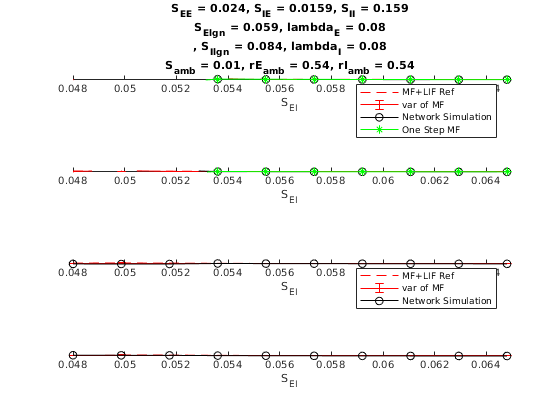

figure('Name','MFEstimation VS Network Simulation')
subplot 411
hold on
%plot(S_EItest,Fr_Fix(1,:),'g')
%scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(1,:,1:MFSampleN)),...
%                                    length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_ref(1,:),'r--')
errorbar(S_EItest,Fr_NoFix_ref(1,:),Fr_NoFixVar_ref(1,:),'r')
plot(S_EItest,Fr_NW(1,:),'k','Marker','o')
plot(S_EItest,Fr_OneStep(1,:),'g','Marker','*')
xlabel('S_{EI}'); ylabel('f_E')
legend('MF+LIF Ref','var of MF','Network Simulation','One Step MF')
xlim([min(S_EItest) max(S_EItest)])
ylim([0 5])
ParameterDisp = ['S_{EE} = ' num2str(S_EE) ...
                         ', S_{IE} = ' num2str(S_IE) ', S_{II} = ' num2str(S_II) '\n' ...
                         'S_{Elgn} = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) '\n' ...
                         ', S_{Ilgn} = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_{amb} = ' num2str(S_amb) ', rE_{amb} = ' num2str(rE_amb) ', rI_{amb} = ' num2str(rI_amb)];
titlePara = sprintf(ParameterDisp);
title(titlePara)

subplot 412
hold on
% plot(S_EItest,Fr_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(Fr_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,Fr_NoFix_ref(2,:),'r--')
errorbar(S_EItest,Fr_NoFix_ref(2,:),Fr_NoFixVar_ref(2,:),'r')
plot(S_EItest,Fr_NW(2,:),'k','Marker','o')
plot(S_EItest,Fr_OneStep(2,:),'g','Marker','*')
xlabel('S_{EI}'); ylabel('f_I')
xlim([min(S_EItest) max(S_EItest)])
ylim([2 20])

subplot 413
hold on
% plot(S_EItest,mV_Fix(1,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(1,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_NoFix_ref(1,:),'r--')
errorbar(S_EItest,mV_NoFix_ref(1,:),mV_NoFixVar_ref(1,:),'r')
plot(S_EItest,mV_NW(1,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_E')
legend('MF+LIF Ref','var of MF','Network Simulation')
xlim([min(S_EItest) max(S_EItest)])

subplot 414
hold on
% plot(S_EItest,mV_Fix(2,:),'g')
% scatter(repmat(S_EItest',MFSampleN,1),reshape(squeeze(mV_NoFix(2,:,1:MFSampleN)),...
%                                     length(S_EItest)*MFSampleN,1),'r.')
plot(S_EItest,mV_NoFix_ref(2,:),'r--')
errorbar(S_EItest,mV_NoFix_ref(2,:),mV_NoFixVar_ref(1,:),'r')
plot(S_EItest,mV_NW(2,:),'k','Marker','o')
xlabel('S_{EI}'); ylabel('mV_I')
xlim([min(S_EItest) max(S_EItest)])

## Fr trajs

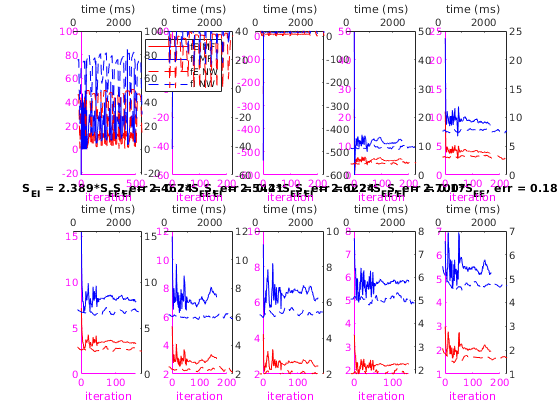

figure('Name','Fr_Traj')
Accuracy = min(abs(Fr_NoFix_ref - Fr_NW)./Fr_NoFix_ref);
Fr_PlotTime = (0:FrWinNum-1)*FrWinStep + FrWinSize;
for S_EIInd = length(S_EItest):-1:1
    subplot(2,5,S_EIInd)
    
    hold on    
    l1 = plot(Fr_NoFixTraj_ref{S_EIInd}(1,:),'r-');
    l2 = plot(Fr_NoFixTraj_ref{S_EIInd}(2,:),'b-');
    xlabel('iteration')
    ax1 = gca; % current axes
    ax1.XColor = [1 0 1];
    ax1.YColor = [1 0 1];
    hold off
    ax1_pos = ax1.Position; % position of first axes
    
    ax2 = axes('Position',ax1_pos,...
    'XAxisLocation','top',...
    'YAxisLocation','right',...
    'Color','none');
    title(sprintf('S_{EI} = %.3f*S_{EE}, err = %.2f', S_EItest(S_EIInd)/S_EE, Accuracy(S_EIInd)))
    hold on
    l3 = plot(Fr_PlotTime,Fr_NWTraj{S_EIInd}(1,:),'r--');
    l4 = plot(Fr_PlotTime,Fr_NWTraj{S_EIInd}(2,:),'b--');
    xlabel('time (ms)')
    ax2.YLim = ax1.YLim;
    ax1.YLim = ax2.YLim;
    if S_EIInd  ==2
        legend([l1;l2;l3;l4], {'fE MF','fI MF','fE NW','fI NW'})
    end
    
end

## Add Accuracy to figure

openfig([FigurePath '/MF_3DCountour_SEI_SIE_S_II_SEE=0.024_rEamb540_rIamb540.fig'],'visible')

ans =   Figure (28: Figure) with properties:

      Number: 28
        Name: 'Figure'
       Color: [1 1 1]
    Position: [1921 1 1920 998]
       Units: 'pixels'

  Show all properties


subplot(1,2,2)
hold on
Accuracy = abs(Fr_NoFix_ref - Fr_NW)./Fr_NoFix_ref;
c = min(Accuracy);
c(isinf(c)) = nan;

scatter(S_IE/S_II*ones(size(c)),...
            S_EItest/S_EE,...
            25,c,'filled')
hold off
colorbar
caxis([0, 0.3]);
mymap = [0 0 1
         0 1 1
         0 1 0
         1 0.5 0
         1 0 0
         1 0 1];
colormap(mymap)

## Save workspace

save('MF_3DValidateWorkSp.mat')